clear all;close all;clc;

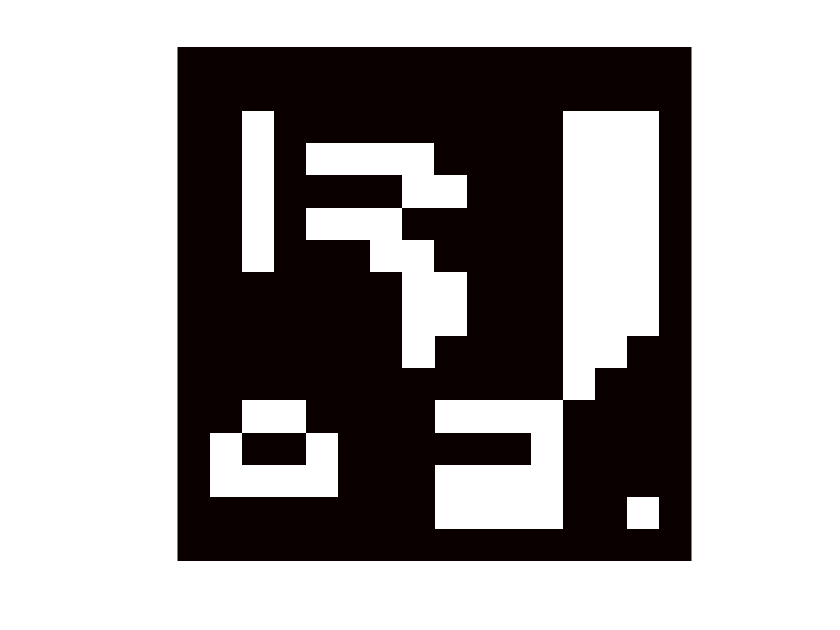

load Image1.mat
imagesc(Image1)
imagegrid(gca,size(Image1));
axis image off;
colormap(gca,hot);

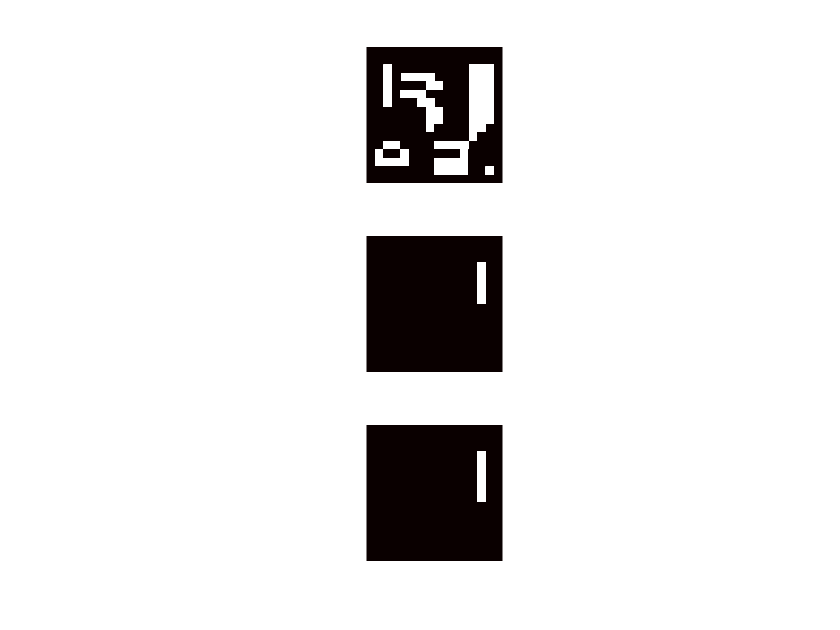

% ex3
se1 = strel('square',3);
se2 = strel('disk',1);
img_1 = imerode(Image1, se1);
img_2 = imerode(Image1, se2);
figure;
subplot(1,3,1);
imagesc(Image1);
imagegrid(gca,size(Image1));
axis image off;
colormap(gca,hot);
subplot(1,3,2);
imagesc(img_1);
imagegrid(gca,size(img_1));
axis image off;
colormap(gca,hot);
subplot(1,3,3);
imagesc(img_2);
imagegrid(gca,size(img_2));
axis image off;
colormap(gca,hot);

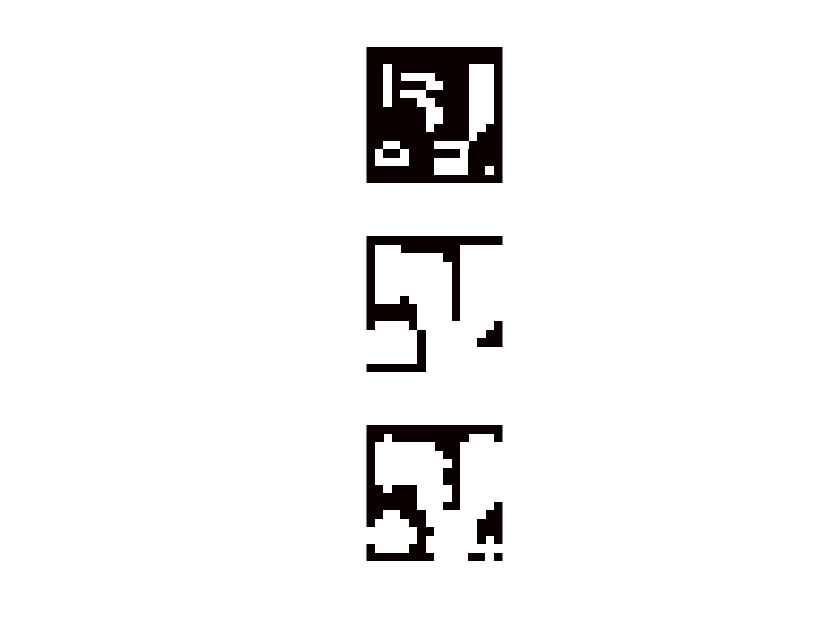

% ex6
se1 = strel('square',3);
se2 = strel('disk',1);
img_3 = imdilate(Image1, se1);
img_4 = imdilate(Image1, se2);
figure;
subplot(1,3,1);
imagesc(Image1);
imagegrid(gca,size(Image1));
axis image off;
colormap(gca,hot);
subplot(1,3,2);
imagesc(img_3);
imagegrid(gca,size(img_3));
axis image off;
colormap(gca,hot);
subplot(1,3,3);
imagesc(img_4);
imagegrid(gca,size(img_4));
axis image off;
colormap(gca,hot);

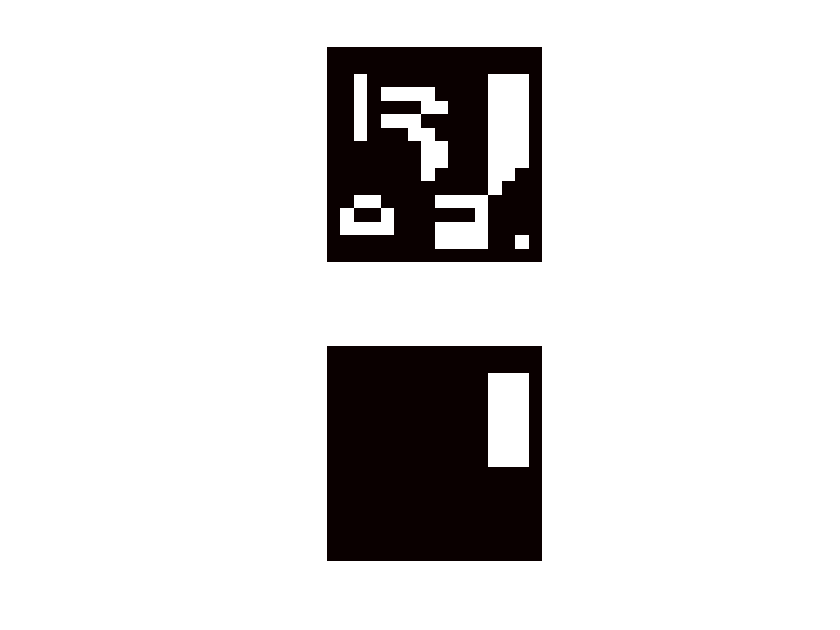

% ex7
img_5 = mopen(Image1,se1);
figure;
subplot(1,2,1);
imagesc(Image1);
imagegrid(gca,size(Image1));
axis image off;
colormap(gca,hot);
subplot(1,2,2);
imagesc(img_5);
imagegrid(gca,size(img_5));
axis image off;
colormap(gca,hot);

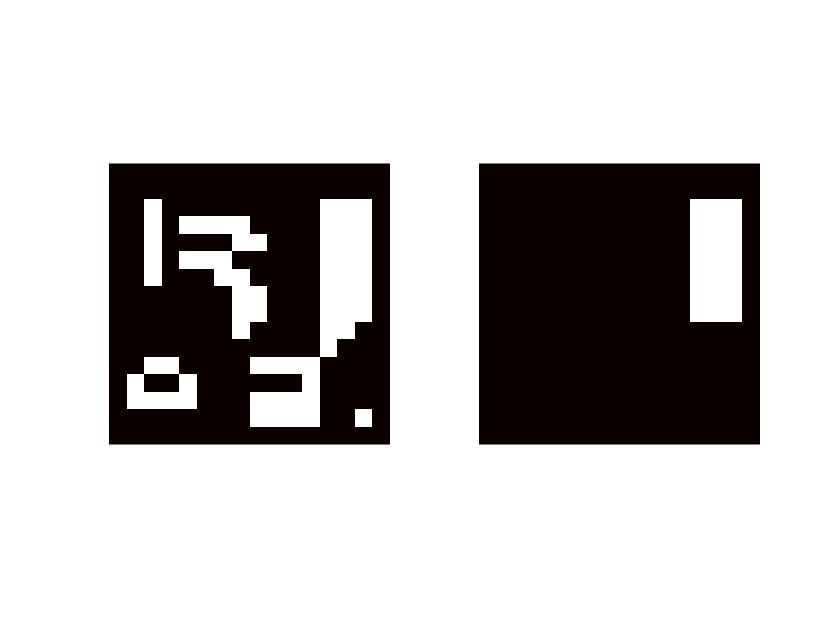

% ex8
img_6 = imopen(Image1,se1);
figure;
subplot(1,2,1);
imagesc(Image1);
imagegrid(gca,size(Image1));
axis image off;
colormap(gca,hot);
subplot(1,2,2);
imagesc(img_6);
imagegrid(gca,size(img_6));
axis image off;
colormap(gca,hot);

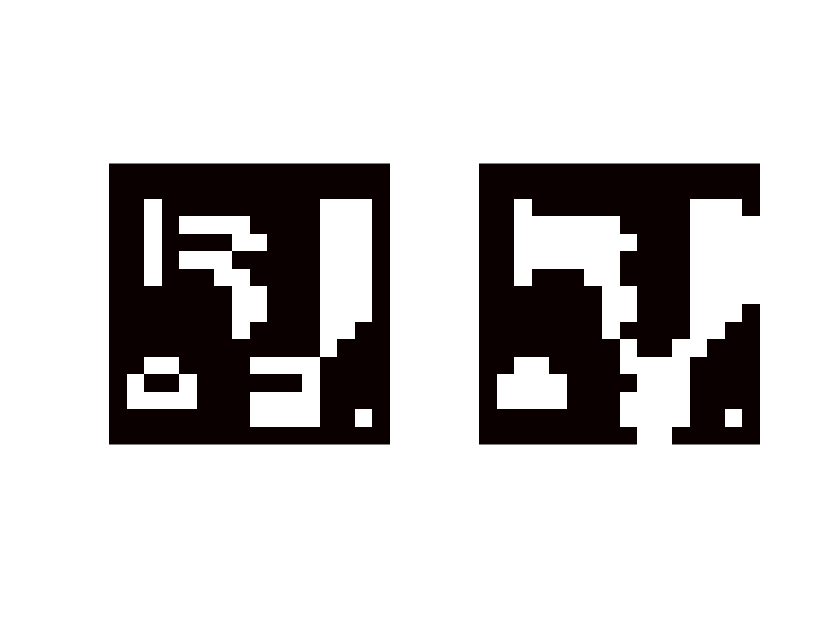

% ex9
img_7 = mclose(Image1,se2);
figure;
subplot(1,2,1);
imagesc(Image1);
imagegrid(gca,size(Image1));
axis image off;
colormap(gca,hot);
subplot(1,2,2);
imagesc(img_7);
imagegrid(gca,size(img_7));
axis image off;
colormap(gca,hot);

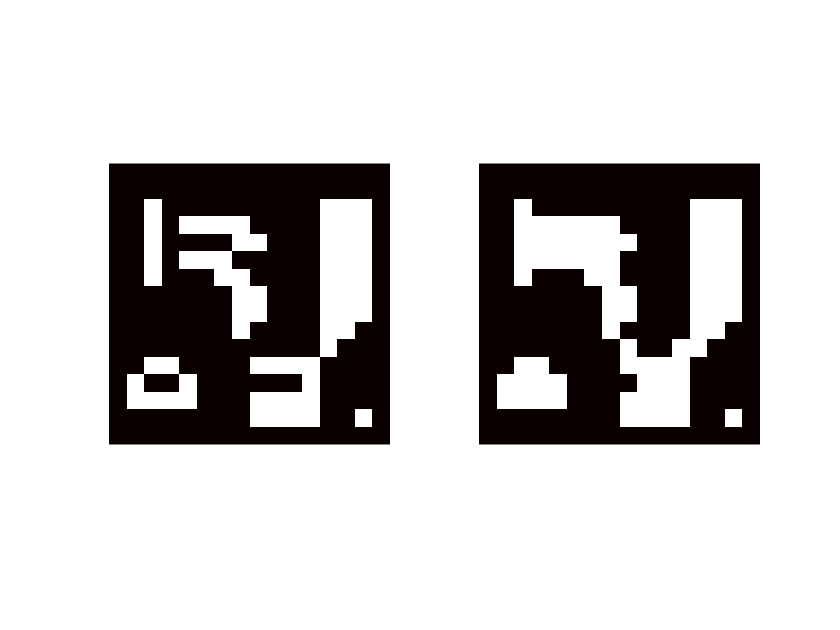

% ex10
img_8 = imclose(Image1,se2);
figure;
subplot(1,2,1);
imagesc(Image1);
imagegrid(gca,size(Image1));
axis image off;
colormap(gca,hot);
subplot(1,2,2);
imagesc(img_8);
imagegrid(gca,size(img_8));
axis image off;
colormap(gca,hot);

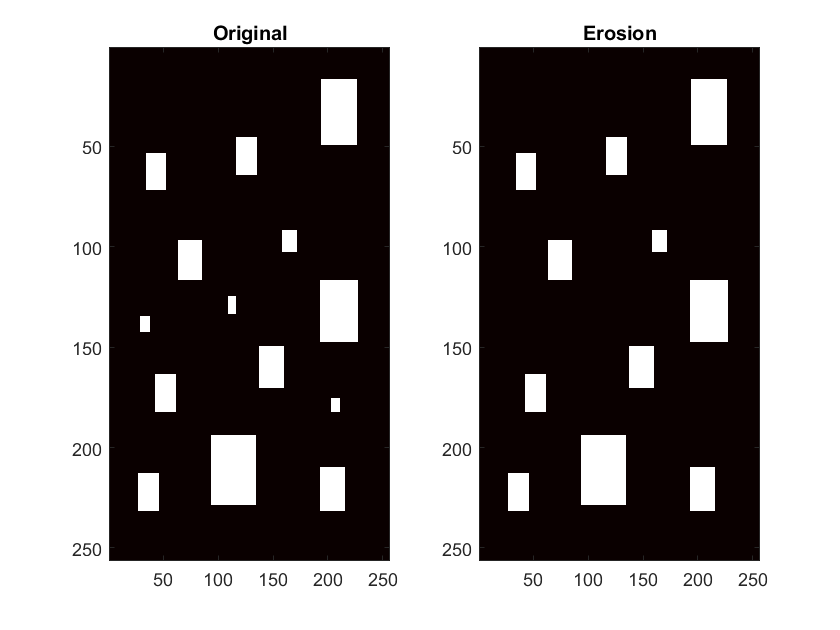

% ex11
load rects.mat
se3 = strel('square',9);
rects_1 = imopen(rects,se3);
figure;
subplot(1,2,1)
imagesc(rects);
colormap(gca, hot);
title('Original');
subplot(1,2,2)
imagesc(rects_1);
colormap(gca, hot);
title('Erosion');

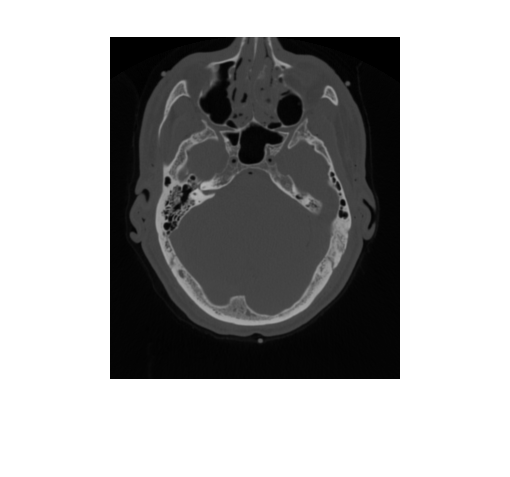

clear all,close all,clc;
I = imread('BrainCT.png');
imshow(I);

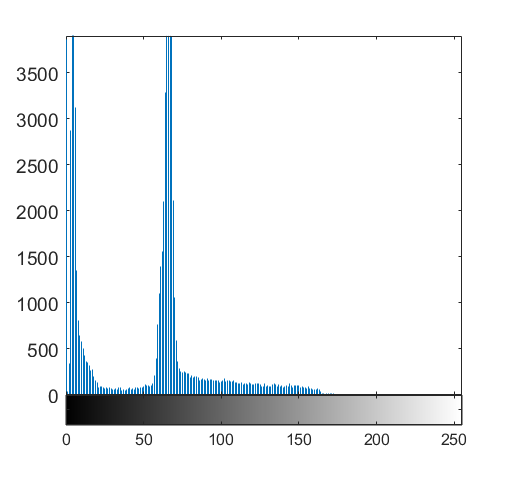

% ex12
imhist(I);

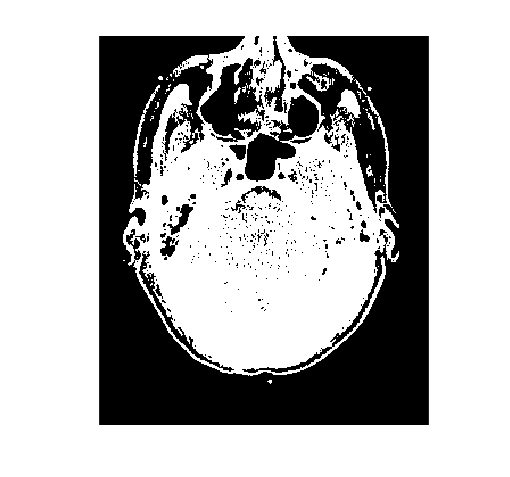

T = 64;
Ibone = I>T;
imshow(Ibone);

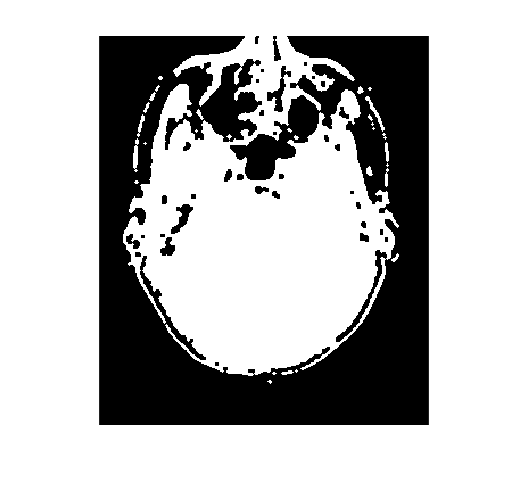

% ex13
se1 = strel('square',3);
se2 = strel('disk',1);
I1 = imclose(Ibone,se1);
Imask = imopen(I1,se2);
imshow(Imask);

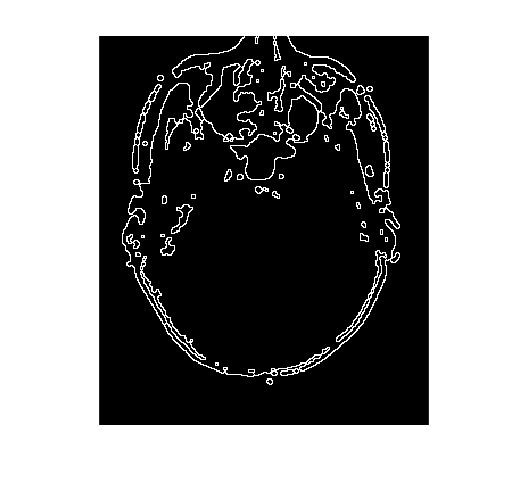

% ex14
I2 = imdilate(Imask,se1);
imshow(I2-Imask);

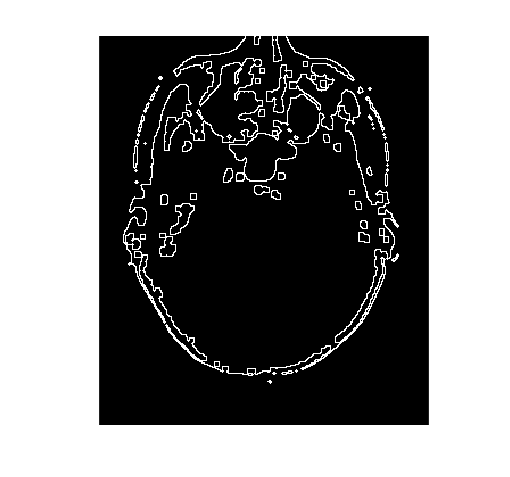

% ex15
I3 = imerode(Imask,se1);
imshow(Imask-I3);

% the width of the boundary of dilation operator is larger than the erosion
% one
